## Лабораторна Робота 1

clear, close all

## 1. Завантажити з бібліотеки MATLAB і відобразити на екрані ПК кілька зображень у різних форматах.

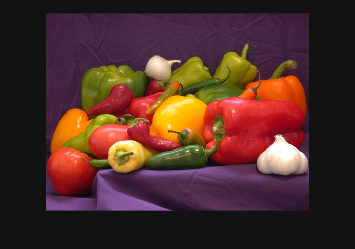

peppers = imread('peppers.png');
imshow(peppers);

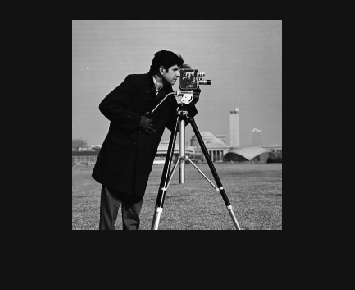

cameraman = imread('cameraman.tif');
imshow(cameraman);

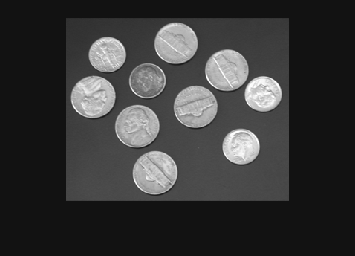

coins = imread('coins.png');
imshow(coins);

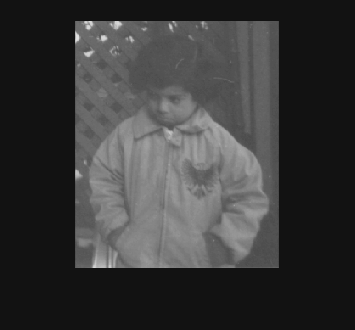

pout = imread('pout.tif');
imshow(pout);

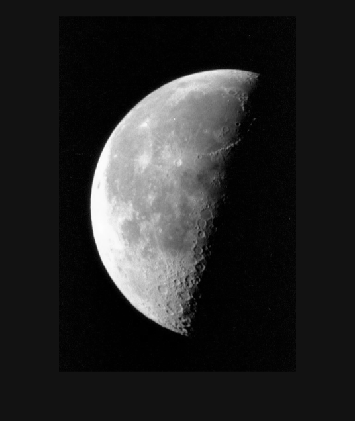

moon = imread('moon.tif');
imshow(moon);

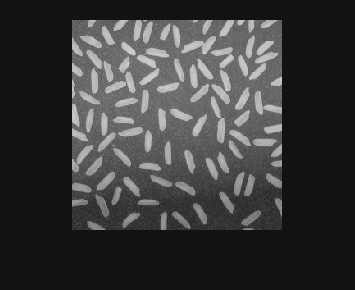

rice = imread('rice.png');
imshow(rice);

## 2. Завантажити зображення, що зберігається в довільному каталозі (з безпосередньою вказівкою шляху до нього).

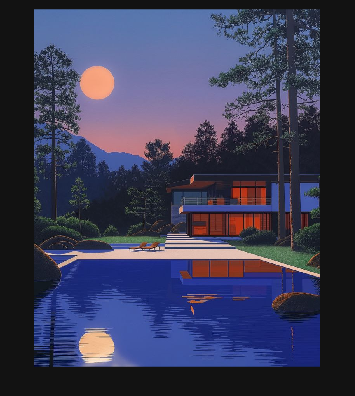

view = imread('D:\Uni\View.jpg');
figure,imshow(view);

## 3.Одержати інформацію про завантажені зображення.

size(view);
whos view;

  Name        Size                 Bytes  Class    Attributes

  view      920x736x3            2031360  uint8              



size(cameraman);
whos cameraman;

  Name             Size             Bytes  Class    Attributes

  cameraman      256x256            65536  uint8              



size(coins);
whos coins;

  Name         Size             Bytes  Class    Attributes

  coins      246x300            73800  uint8              



size(moon);
whos moon;

  Name        Size              Bytes  Class    Attributes

  moon      537x358            192246  uint8              



## 4. Зберегти завантажені зображення в заданому каталозі з указівкою шляху до нього.

% imwrite(cameraman, "img/save/cameraman.jpg");
% imwrite(view, "img/save/view.jpg");
% imwrite(dark, "img/save/dark.jpg");
% imwrite(moon, "img/save/moon.jpg");
% imwrite(peppers, "img/save/peppers.jpg");
% imwrite(pout, "img/save/pout.jpg");

## 5. З використанням процедури imhist(I) знайти гістограми розподілу яскравостей завантажених зображень і відобразити їх на екрані ПК.

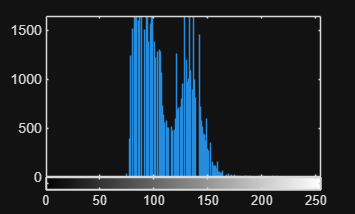

imshow(pout),figure,imhist(pout);

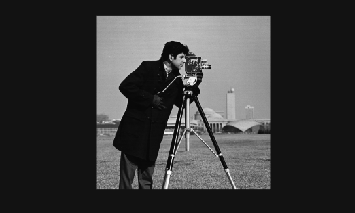

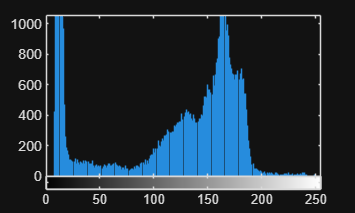

imshow(cameraman),figure,imhist(cameraman);

## 6. З використанням процедури imadjust(I); виконати контрастування зображень.

## та

## 7. Відобразити зображення з підвищеною контрастністю на екрані ПК.

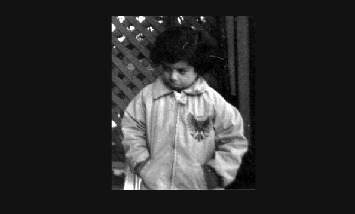

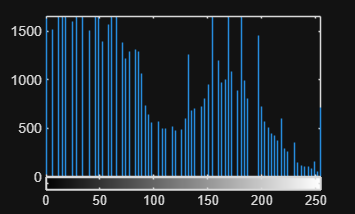

pout_adj = imadjust(pout);
imshow(pout_adj),figure,imhist(pout_adj);

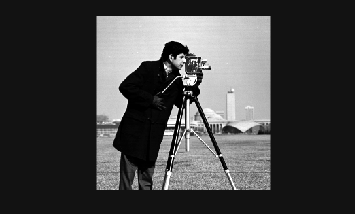

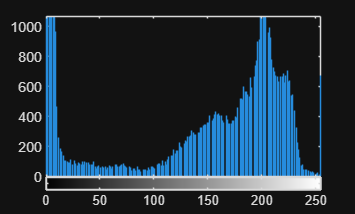

cameraman_adj = imadjust(cameraman);
imshow(cameraman_adj),figure,imhist(cameraman_adj);

## 8. Відобразити негатив зображення I.

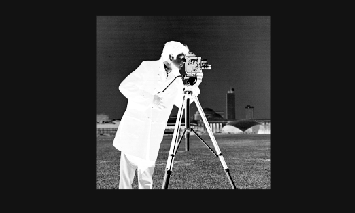

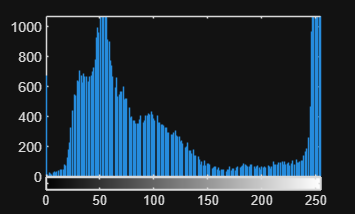

cameraman_adj_neg = imadjust(cameraman_adj,[0,1],[1,0],1);
imshow(cameraman_adj_neg),figure,imhist(cameraman_adj_neg);

## 9. З використанням Help MATLAB ознайомитися більш детально з особливостями процедури контрастування зображень imadjust.  

help imadjust

 imadjust - Adjust image intensity values or colormap
    This MATLAB function maps the intensity values in grayscale image I to
    new values in J.

    Syntax
      J = imadjust(I)
      J = imadjust(I,[low_in high_in])
      J = imadjust(I,[low_in high_in],[low_out high_out])
      J = imadjust(I,[low_in high_in],[low_out high_out],gamma)

      J = imadjust(RGB,[low_in high_in],___)
      newcmap = imadjust(cmap,[low_in high_in],___)

    Input Arguments
      I - Grayscale image
        m-by-n numeric matrix
      RGB - Truecolor image
        m-by-n-by-3 numeric array
      cmap -

Основний формат функції: 

`J = imadjust(I, [low_in high_in], [low_out high_out], gamma)`

де:

`I` - вхідне зображення

`[low_in high_in]` - діапазон вхідних інтенсивностей які будуть відображені

`[low_out high_out]` - діапазон вихідних інтенсивностей

`gamma` - параметр гамма-корекції